# **Colony Growth: Simulation and Chi^2 Fitting of Growth Rate**

**Physical Biology of the Cell: Day 1 (March 25, 2019)**

We just plotted area of colony over time. But what we really want to get out of this is the doubling time, i.e. the time it takes to double the mass. Now we're going to explore a model of bacterial growth. 

# Part I: Model for Bacteria Growth

Since our goal is to use regression analysis (i.e. find the relationship between variables, number of bacteria and the rate of change their number) to estimate a parameter (i.e. growth rate $k$), we of course need a model how these variables are related to one another. To develop this model, we will assume that each bacterium growth at a constant rate (i.e. $k$ is constant) . Then the total mass or number, of bacteria, will grow more rapidly as we get more bacteria. We can write this as a differential equation.


$$\dot{N} = \frac{d N(t)}{dt} = k * N(t)$$


Where $N\left(t\right)$is the number of cells at time, t, and $k$is the growth rate in units of 1/min - this is related to how often the cells split in two. This is a ordinary differential equation (ODE) describing the rate of cell division. We can either solve this ODE analytically (exponential growth) or numerically. A simple yet powerful method for numerical integration is called Euler's method. Here, we use this method to simulate the change in the number of cells over time. Euler’s method is an algorithm for integrating the dynamics of a system given one or more differential equations describing the rate of change of system components (in our case cells), and an initial condition (how many cells we start with). 

Given an ODE $y\prime = f(t,y)$, Euler's method uses the slope of $y$ at each time, $t$, to estimate the value of $y$ at time $t+\Delta t$. It follows the equation


$$y(t + \Delta t) = y(t) + \Delta t * y\prime(t)$$


For our ODE, this is written as 


$$\text{ }$$

$$N\left(t+\Delta t\right)=N\left(t\right)+\Delta t*k*N\left(t\right)$$


We're going to use the Euler method to find the numerical solution to the growth curve - i.e. to predict the number of cells that accumulate over time. We're first going to do this from a single cell. We're then going to take the actual data (we got from image segmentation) and find the model that best fits this data. 

% Define the variables for the simulation: 
% Initial condition, growth rate, time step, total time running simulation
% We have to commit to these things in order to run it. 

N0 = 1;          % Initial condition: number of cells you start off with
k = 1/30;        % Growth rate in min^-1. This is an estimate. We will find the best fit later.
dT = 15;         % Time step (this needs to be shorter than the doubling time). 
dTlong = 45;     % To see why this matters, we'll also look at what happens when we use a timestep longer than the DT


Let's compute the number of cells at the first timepoint manually - this helps us see what we need to do. Remember the equation from above:

N1 = N0 + k * N0 * dT

N1 = 1.5000

Now we're going to do the same thing for all the subsequent timepoints. What we're going to end up with is a vector, N, of the number of cells at each time step. What needs to be in the first entry in that vector

% The first entry in the array is going to be the number of cells at t=0
N(1) = N0;
Nlong(1) = N0;

% Use a for loop to record the number of cells - PUT IN MORE PSEUDOCODE
for i = 2:50         % remember that the first entry is already filled!
    % Use the above equation to calculate the number of cells at time i
    N(i) = N(i-1) + k * N(i-1) * dT;
    Nlong(i) = Nlong(i-1) + k * Nlong(i-1) * dTlong;
    
    % Generate a time vector to plot this data against
    TimeVectSim(i) = (i-1)*dT;
    TimeVectSimLong(i) = (i-1)*dTlong;
end


Plot the outcome 

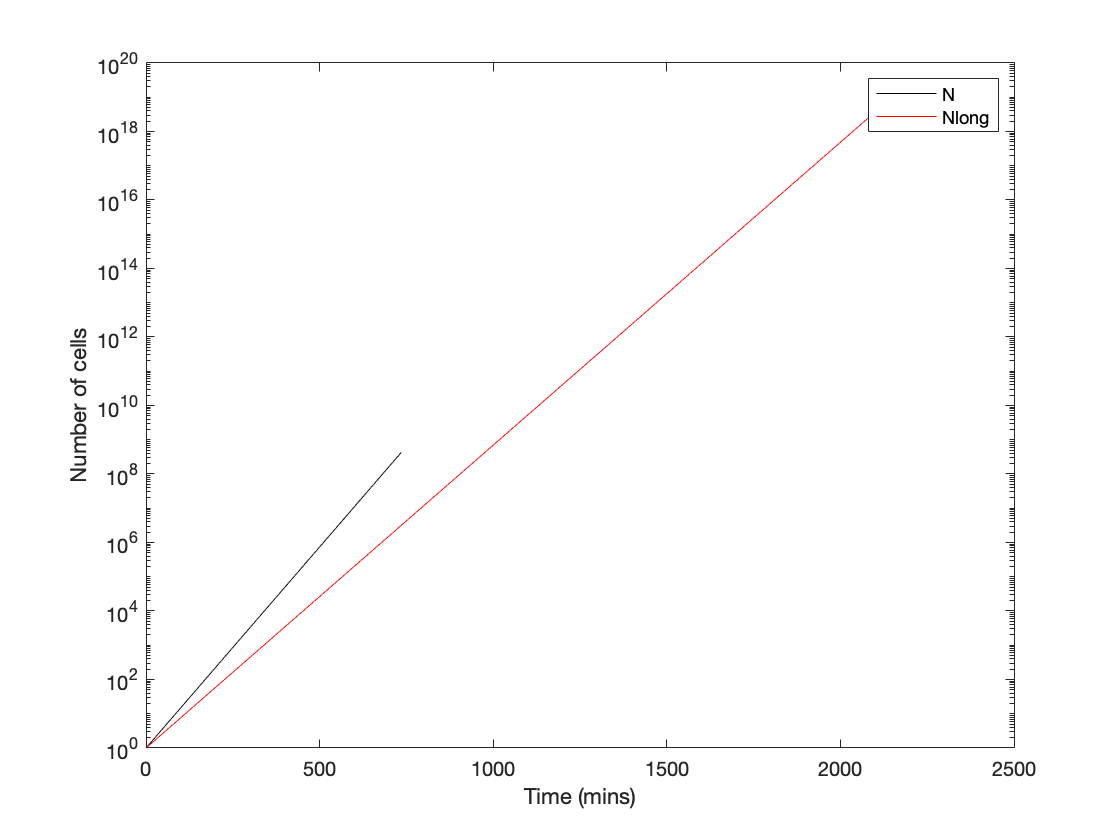

% Use a semilog scale
figure(1)
semilogy(TimeVectSim,N,'-k')

% In order to plot the simulation with the longer timestep on the same plot, use the hold on command
hold on
semilogy(TimeVectSimLong,Nlong,'-r')    % this will plot it as a dotted line, to distinguish it from the above curve for N
xlabel('Time (mins)')
ylabel('Number of cells')
legend('N', 'Nlong')        % we can also make a legend so we can identify which line is which

hold off

You can see from the plot that the longer timestep under-estimates the number of cells in the colony compared to the shorter time step. 

# Part II: Fitting to find the best value for the growth rate, k

## Introduction to the Chi-square statistic

What we want to do is to estimate the value of k that **best describes** the data we have (the growth of the bacterial colony) under a given model - the model of exponential growth. So in other words, what we're doing is trying to find the most representative value of the growth rate. 

But what do we mean by "best describes" the data? Let's think about an imaginary set of data in which x and y are linearly correlated. We can draw a line through this data, $y=\text{ }a\ast x$, where $a$ is the slope, which is the parameter we want to estimate. 

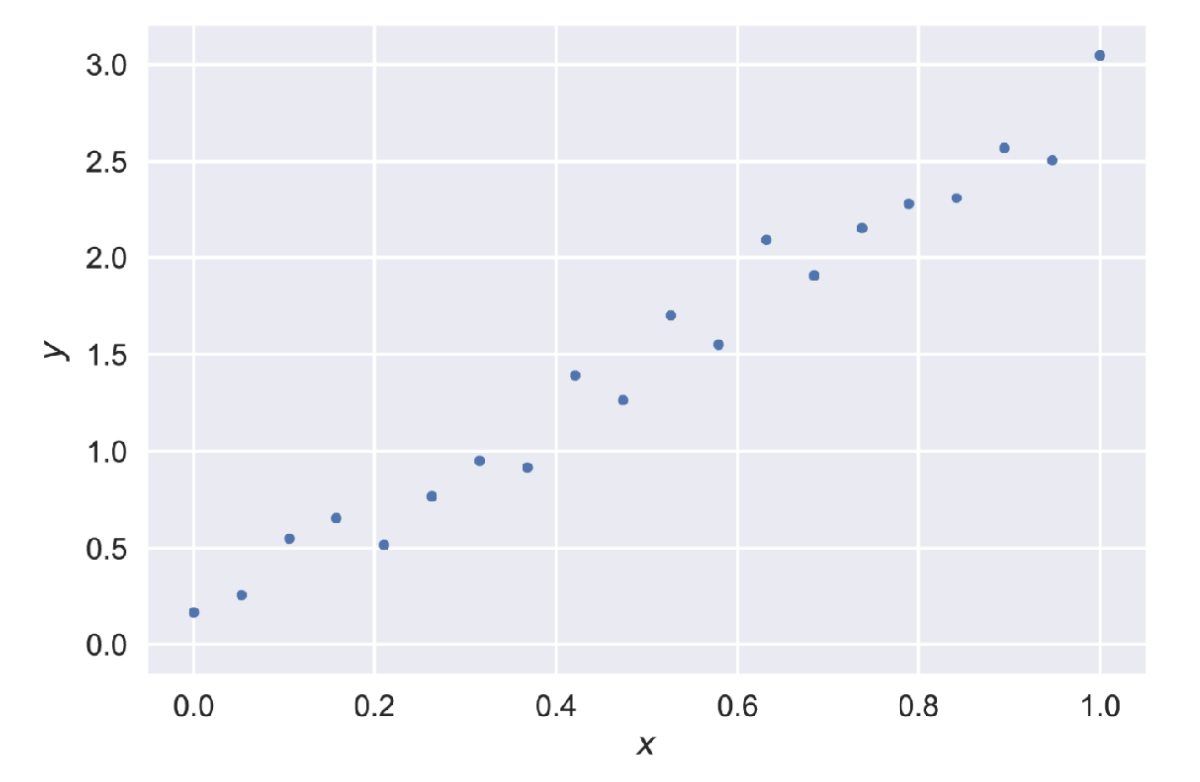

Intuitively, we can imagine that the best estimate of $a$ is the value where the difference of each data point and the line resulting from our model is the smallest. These values are the residuals. 

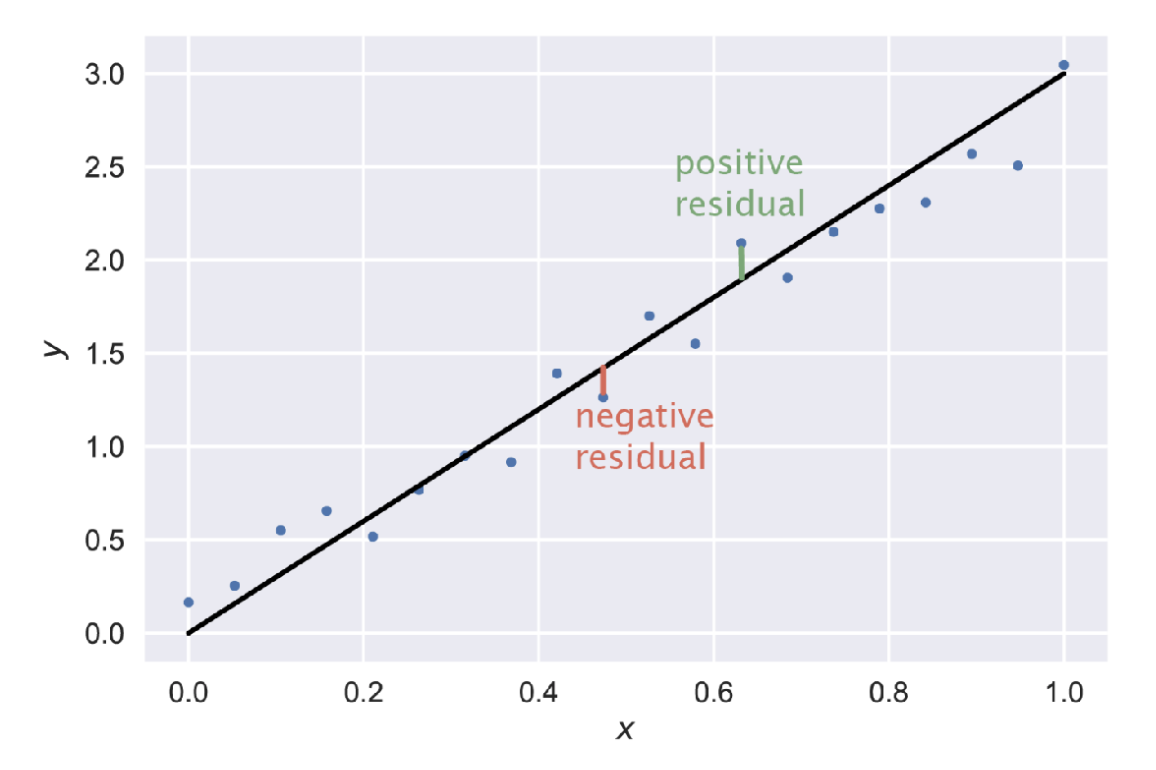

If we assume that the errors in this data are identically distrubuted - i.e. that there are no outliers - then we can use the Chi-square statistic to compute the sum of the squares of the residuals for a range of values of $a$ and then find where this sum is at its minimum. 

The equation for this is: 

   
$$\chi^2 =\sum_{i} \frac{{\left(y_i -y\text{ }\left(a\right)\right)}^2 }{\sigma_i^2 }$$


Here, $y_i$ is the *ith* datapoint, $y\left(a\right)$ is the predicted value of $y$, given a specific value of $a$, and $\sigma_i^2$ is the variance of the data. 

In our specific case, it is 


$$\chi^2 =\sum_{i} \frac{{\left({\mathrm{Area}\text{ }}_i -N\text{ }\left(k\right)\right)}^2 }{\sigma_i^2 }$$


where N is the simulated colony area, given value for the growth rate, k, and Area is the actual area of the colony. We're going to ignore $\sigma_i^2$. 

## Load the colony area dataset

We're going to load a dataset of the colony area from the movie - just so that we all have the same dataset to work from. 

% Load the .csv file
data = csvread('Growth_area.csv');        % You'll need to be in the same folder as this file in order to open it like ths
time = data(:,1);
area = data(:,2);                                        

## Looking at our data

Let's plot the data set using black points

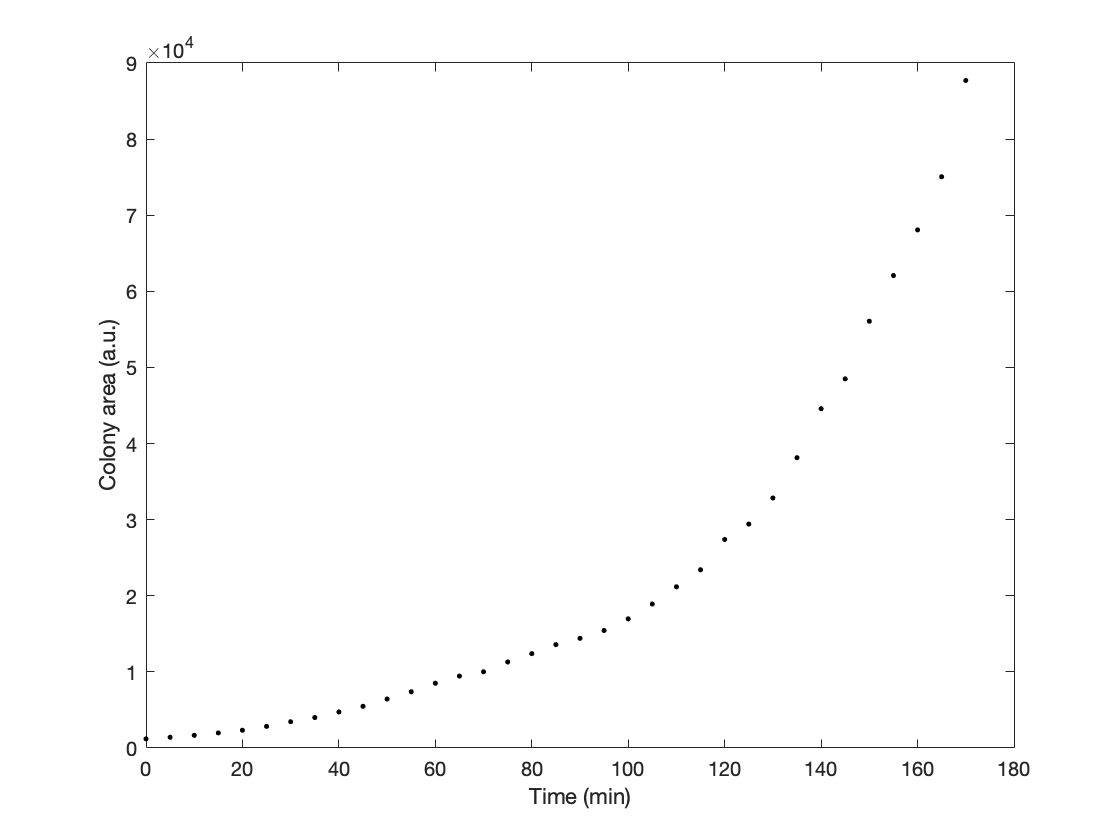

plot(time,area,'.k')
xlabel('Time (min)')
ylabel('Colony area (a.u.)')

It looks like we're not really capturing all the information in the data with this plot. Let's try by repeating this plot, but now using a log-scale on the y-axis using `semilogy`.

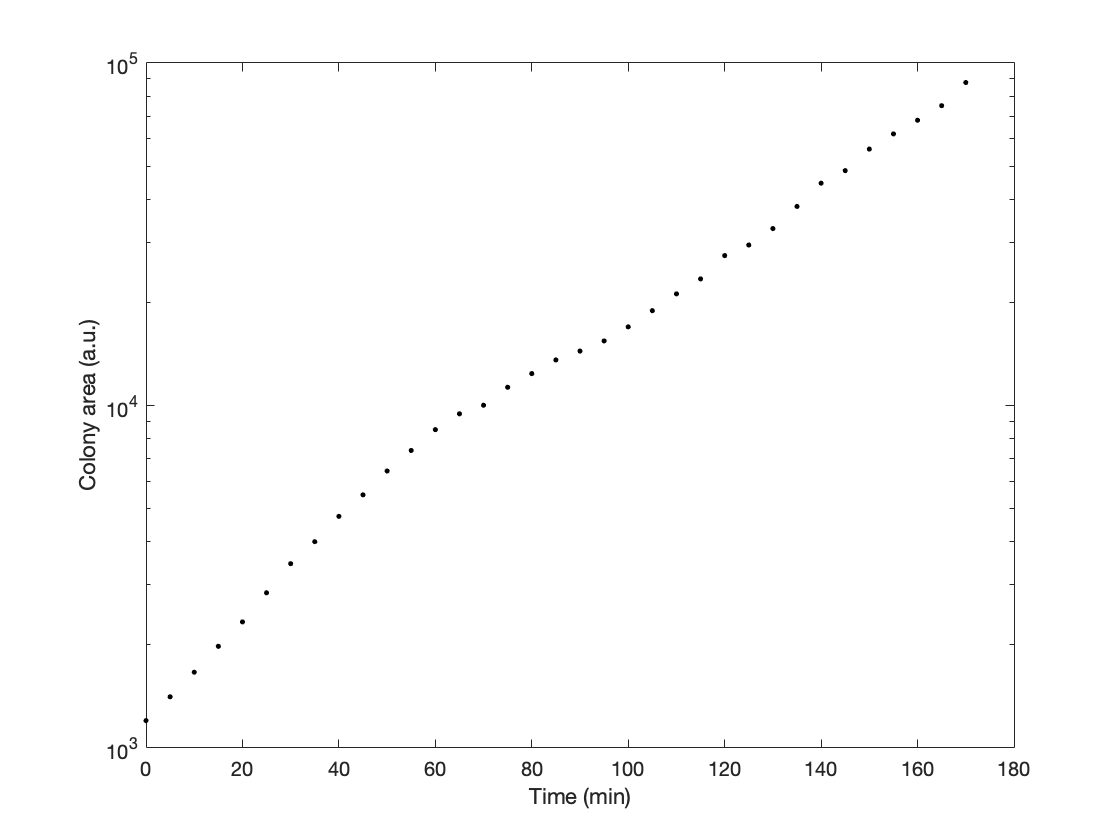

semilogy(time,area,'.k')
xlabel('Time (min)')
ylabel('Colony area (a.u.)')

Remember that we expect to get exponential growth. On a log-axis, this growth should look linear. Clearly, there's an initial linear stage of our data, but the data after 100min doesn't seem to follow this functional form. This is probably due to the fact that our segmentation missed big parts for the colony towards these later frames. As a result, we can chooset to fit only the first few data points of our data. Such a range can be invoked by doing

per = 0.9; %percentage of data points to consider 
data_points = floor(length(area)*per); %number of data points
area_trunc = area(1:data_points);
time_trunc = time(1:data_points);

Let's combine the full range of data and the limited range

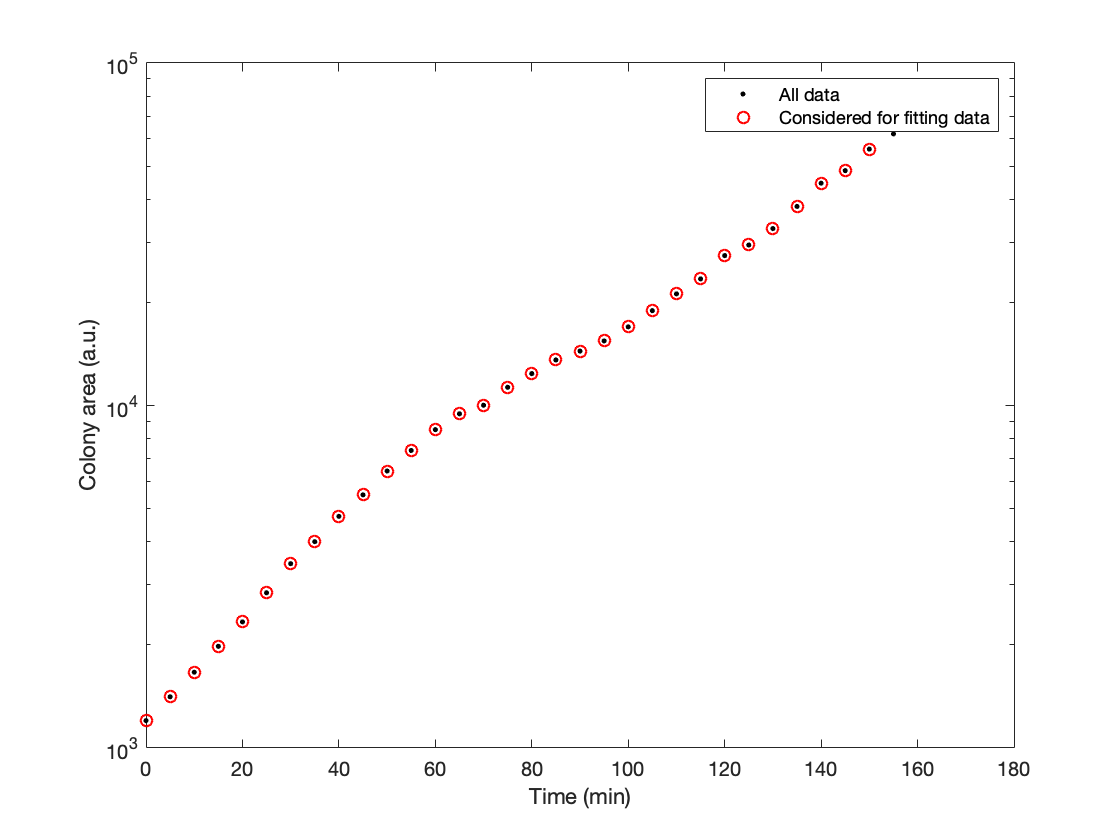

semilogy(time,area,'.k')
hold on
semilogy(time_trunc,area_trunc,'or')
hold off
xlabel('Time (min)')
ylabel('Colony area (a.u.)')
legend('All data','Considered for fitting data')

## Compare data to simulation

We need to define a range of rates, r, over which to search for the best fit. We know that bacteria divide around once every 30 mins. That is, there is one doubling event every 30 minutes, i.e. rate is ~ ln(2)/30, which is ~ 0.02. So it seems reasonable to try a range around this value:

kRange = [0.01:0.0001:0.05];

As an example, we're first going to find the error for a particular value of r from that range - we'll pick 0.02. 

% Error for kTest
kTest = 0.02;         % we're just picking one value of k to practise calculating the error on 

Before we can compare the data to our simulation of exponential growth, we need to calculate the area of the colony using this test value of k! 

Above, we did this using the Euler method, by looping through this equation for each time point:


$$N\left(t+\Delta t\right)=N\left(t\right)+k\ast N\left(t\right)\ast \Delta t$$


The solution to our ODE is:


$$N\left(t\right)=N_0 \ast {e\text{ }}^{k\text{ }t}$$


where $N_0$ is the number fo cells at t = 0 (i.e. the initial condition). We're going to use this to find the number of cells at each timepoint, $N\left(t\right)$. 

## Calculate the error for one value of *k*

As we saw above, in order to simulate the growth of the colony, we need to** specify an initial condition**

% We need to establish the initial condition. In the simulation above we set this as a single cell. But in order to
% simulate our colony growth data, we need to make the initial condition the area at the first timepoint, i.e. at t=0. 

% N is going to once again be the array that will contain our colony size (now in area rather than cell number)
N(1) = area(1);    % N is going to once again be the array that will contain our colony size 
                   % (now in terms of area rather than cell number); Area is the vector containing our data

Now we're going to employ the chi^2 equation above to calculate the error. 

% Calculate the difference between the simulated and the actual data for the test value of k we defined above. 
errorTest = sum((log(area_trunc)-(log(N(1))+kTest*time_trunc)).^2)    

errorTest = 12.4238

This equation looks a little complex, so let's break it down: 

- The lefthand side of the equation inside the sum(..) is the vector of the actual data; we are taking the log of it because ...

- The righthand side of the equation inside the sum(...) is the fit, $N\left(k\right)$, which is described by the equation $N\left(t\right)=N_0 \ast {e\text{ }}^{k\text{ }t}$. We also take the log of this. 

                    Since $\mathrm{log}\left(a\ast b\right)=\mathrm{log}\left(a\right)+\mathrm{log}\left(b\right)$, we can rewrite this as 


$$\log \left(N\left(t\right)\right)=\log \left(N_0 \right)+\log \left(e^{\;k\;t} \right)$$


                    and since log(exp(a)) = a, 


$$\log \left(N\left(t\right)\right)=\log \left(N_0 \right)+k\;t$$


                    which you can see is the righthand side of the equation. 

## And now we can find the error for all the values of k in the range kRange

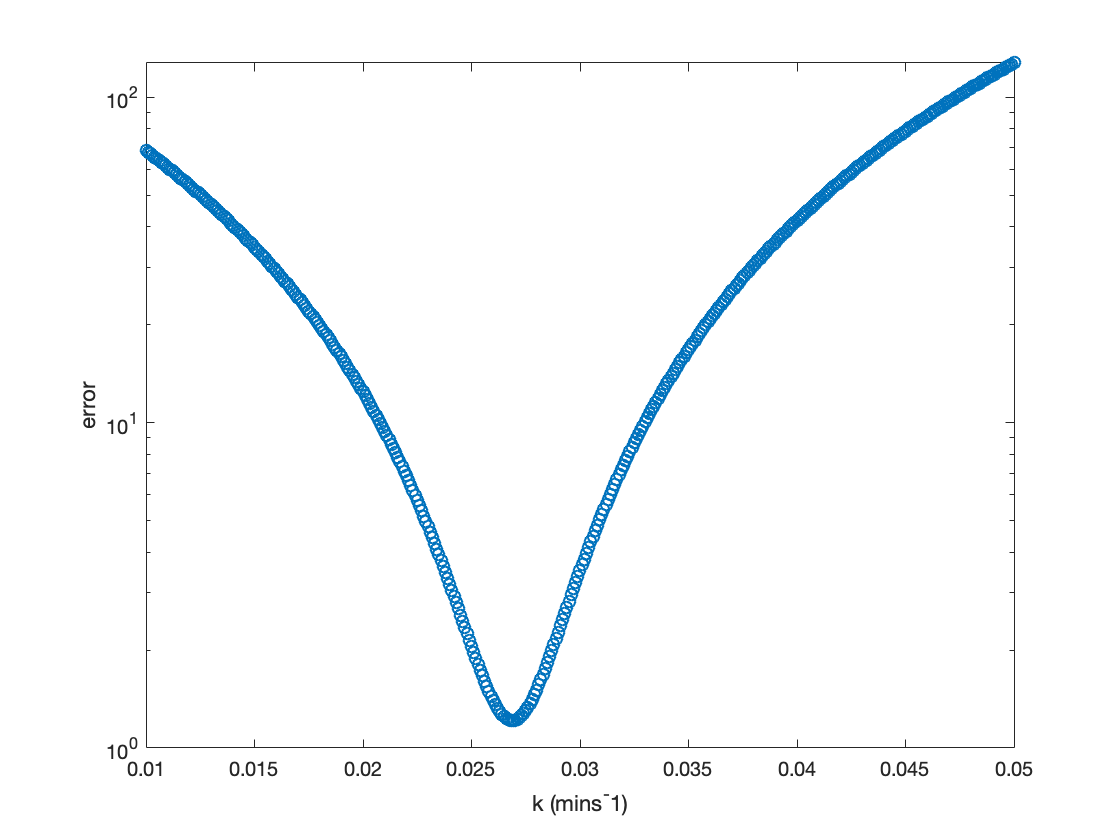

error = zeros(length(kRange),1);
for i = 1:length(kRange)
    error(i) =  sum((log(area_trunc)-(log(N(1))+kRange(i)*time_trunc)).^2);
end

%Let's plot this so that we can eyeball what the minimum is
semilogy(kRange, error, 'o')
xlabel('k (mins^-1)')
ylabel('error')

Now we need to estimate by eye the best fit value of k and define that as kFit

% From the error plot above, we can zoom in to get a good estimate for the value of k (on the x-axis) that looks to
% minimise the error (on the y-axis)
[~,indx]= min(error);                % Insert the best fit k value here
kFit = kRange(indx)

kFit = 0.0269

This corresponds to a growth rate

log(2)/kFit

ans = 25.7676

It looks like the doubling rate is on the order of 43min. Does this make sense if you look at the first few divisions in the movie?

Let's now calculate the best fit given the kFit we obtained

bestFit = (N(1))*exp(kFit*time_trunc);

## Plot the best fit of our data

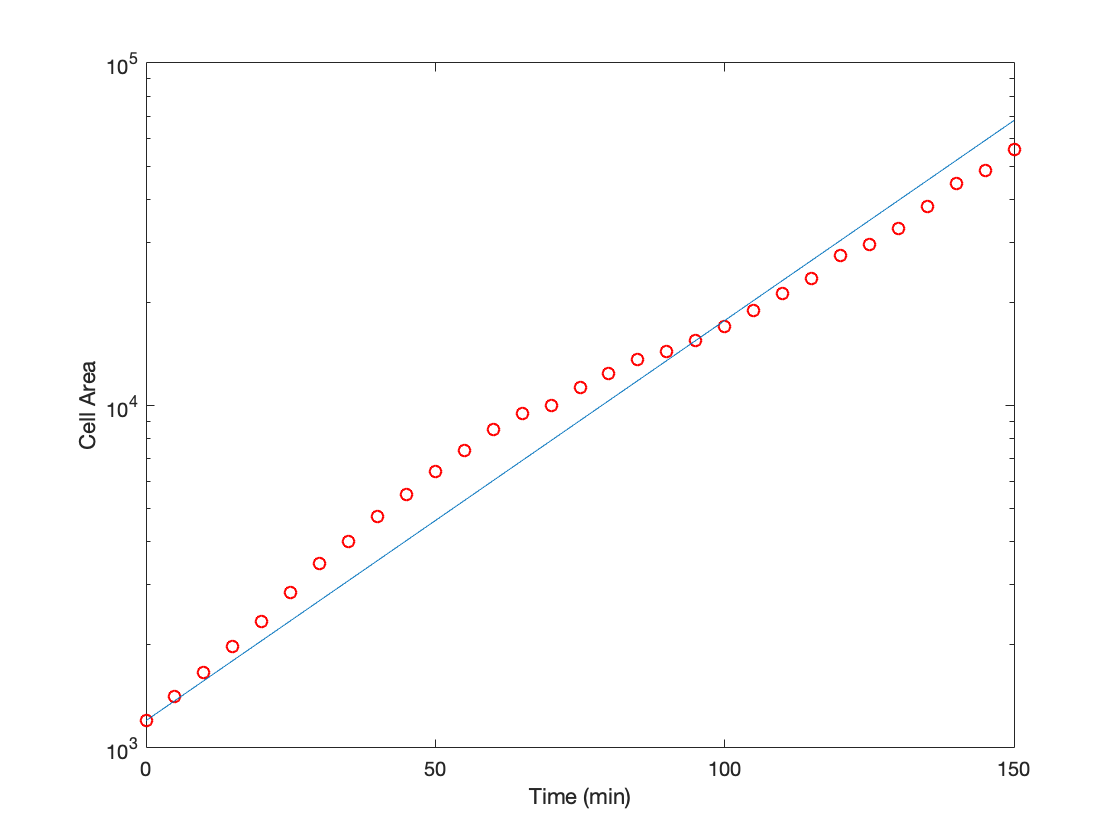

% Plot our data from above
semilogy(time_trunc,area_trunc,'ro')
hold on
% Plot the fit on top of our data
semilogy(time_trunc,bestFit)
hold off
xlabel('Time (min)')
ylabel('Cell Area')